## Pick & Place with collision avoidance with RRT and Evaluation on the real Franka Robot

The current demo combines the following 2 MATLAB demos from Mathworks:

- [Pick and Place Using RRT for Manipulators](https://www.mathworks.com/help/robotics/ug/pick-and-place-using-rrt-for-manipulators.html)

- [Choose Trajectories for Manipulator Paths](https://www.mathworks.com/help/robotics/ug/choose-trajectories-for-manipulator-paths.html?searchHighlight=subplot&s_tid=doc_srchtitle)

And add the element of deployment and testing to the real Franka Robot using functions from the provided MATLAB API.

### Environment setup

% Helper function to load the Franka Robot and a simple 
% environment of collision objects placed in the robot model world.
% Copyright 2020 The Mathworks, Inc.
%  Copyright (c) 2023 Franka Robotics GmbH - All Rights Reserved
%  This file is subject to the terms and conditions defined in the file
%  'LICENSE' , which is part of this package
% exampleHelperLoadPickAndPlaceRRT
% Helper function to load the Franka Robot and a simple 
% environment of collision objects placed in the robot model world.

% The Franka Robot inertial elements are missing. For the purposes
% of motion planning (since dynamics is not involved), it is acceptable to ignore this warning.
warnState = warning("off", "robotics:robotmanip:urdfimporter:IntertialComponentsMissing");
cleanup = onCleanup(@()warning(warnState));
% Load the robot model
franka = loadrobot("frankaEmikaPanda", "DataFormat","row");

% Open the gripper during planning
franka.Bodies{10}.Joint.HomePosition = 0.04;
franka.Bodies{11}.Joint.HomePosition = 0.04;
franka.Bodies{10}.Joint.PositionLimits = [0.04, 0.04];
franka.Bodies{11}.Joint.PositionLimits = [0.04, 0.04];

% Calling the checkCollision function on the robot can aid in finding which
% link-pairs of the robot are in collision.
% Notice that the robot is in self-collision in its home configuration because link 7 and link 11 collide with
% link 5, and link 9 is in collision with link 7. 
[isColliding, sepdist, ~] = checkCollision(franka, homeConfiguration(franka), "Exhaustive", "on");
[r, c] = find(isnan(sepdist));

% Modify the home configuration of the robot
config = [-0.020872218745932 -0.689011339558099 -0.003550760763887 -2.361784826482868 -0.003896808750359 1.685614669146659 0.698361973161831 0.04 0.04];

% Replace the link 9's collision cylinder with a close approximation which
% isn't in collision with link 7
clearCollision(franka.Bodies{9});
addCollision(franka.Bodies{9}, "cylinder", [0.07, 0.05], trvec2tform([0.0, 0, 0.025]));

% Create environment as a set of collision objects.
belt1 = collisionBox(1.3, 0.22, 0.22);
barricade = collisionBox(0.55, 0.085, 0.30);

TBelt1 = trvec2tform([0 -0.18-0.17 0.22/2]);

belt1.Pose = TBelt1;
barricade.Pose = trvec2tform([0.50, -0.20, 0.265]);
cylinder1 = collisionCylinder(0.025, 0.2);

TCyl = trvec2tform([0.45 0.12 0.2/2]);

cylinder1.Pose = TCyl;
env = {belt1, barricade, cylinder1};

### Load Robot Model and Environment

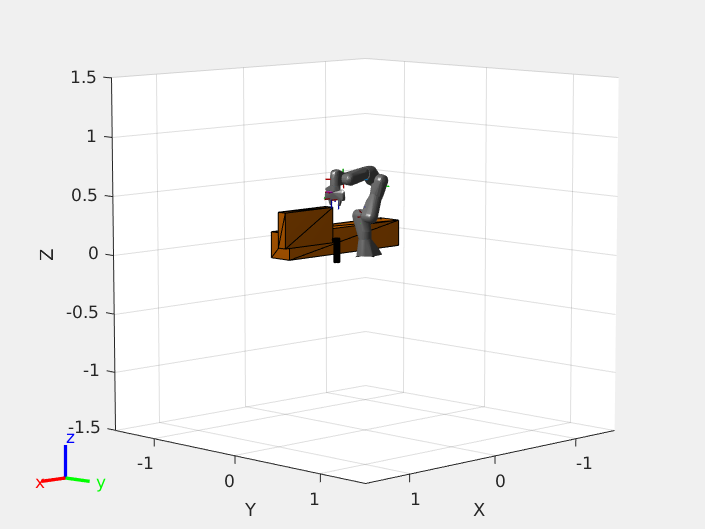

f = figure("Name","Visualising Robot & Environment",...
    "Units","normalized",...
    "Visible","on");

show(franka,config,"Visuals","on","Collisions","off");

hold on
for i = 1:length(env)
    show(env{i});
end

### Initial physical robot configuration setup

We start by Instantiating the franka robot class. Change the IP if necessary to match your own local configuration.

% fr = FrankaRobot('RobotIP','172.16.0.2');

In case of an AI Companion or Jetson Platform you can do the following. Please make sure that the ssh key has been copied from host to target.

(***Make sure that you have copied the ssh key at the target machine and that you've established communication with the target pc!***)

fr = FrankaRobot(   'RobotIP','172.16.0.2',...
                    'Username','user', ...
                    'ServerIP','172.16.1.2',...
                    'SSHPort','22');

Additional parameters can be set in case of a remote target platform, 'SSHPort' and 'ServerPort

Attempt flushing any current potential error states

fr.automatic_error_recovery();

Let's move to initial configuration for this experiment

fr.joint_point_to_point_motion(config(1:7), 0.3);

Let's perform a gripper homing

fr.Gripper.homing();

## Path planning for grasping pose approach

Create the RRT path planner and specify the robot model and the environment. Define some parameters, which are later tuned, and specify the start and goal configuration for the robot.

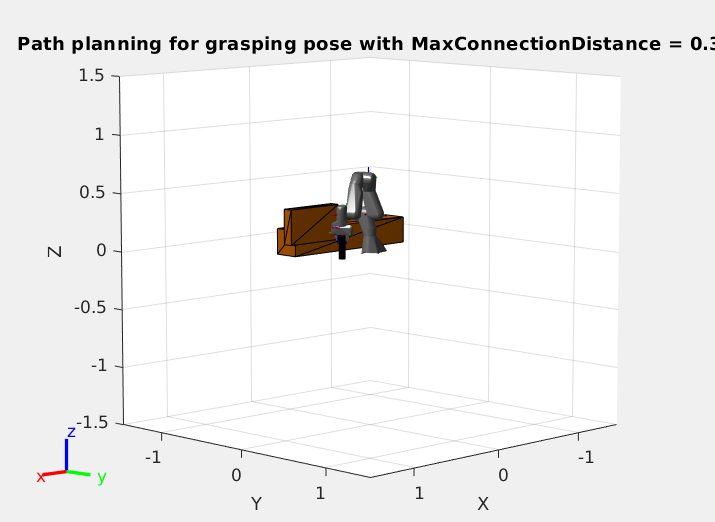

planner = manipulatorRRT(franka, env);

planner.MaxConnectionDistance = 0.3;
planner.ValidationDistance = 0.1;

startConfig = config;
goalConfig = [0.245823224193455 0.0646139385923117 0.020930171872963 -2.46494627383717 -0.00309768510009679 2.50808584313922 0.821267378930416 0.04 0.04];

rng('default');
planned_path =  plan(planner,startConfig,goalConfig);

interpStates = interpolate(planner, planned_path);
figure(f);
for i = 1:2:size(interpStates,1)
    show(franka, interpStates(i,:),...
        "PreservePlot", false,...
        "Visuals","on",...
        "Collisions","off");
    title("Path planning for grasping pose with MaxConnectionDistance = 0.3")
    drawnow;
end

### Trajectories for Manipulator Paths

A joint-space trajectory typically contains a set of waypoints of multiple robot configurations connected using smooth motion. This example generates a trajectory using a trapezoidal velocity profile, which progressively speeds up each joint to a maximum velocity and slows it down as it approaches the next waypoint. For more information, see Trapezoidal Velocity Profile Trajectory. Generate a trapezoidal velocity profile trajectory to connect waypoints for a Franka Robot. First, define the time vector for the trajectories and load the robot model.

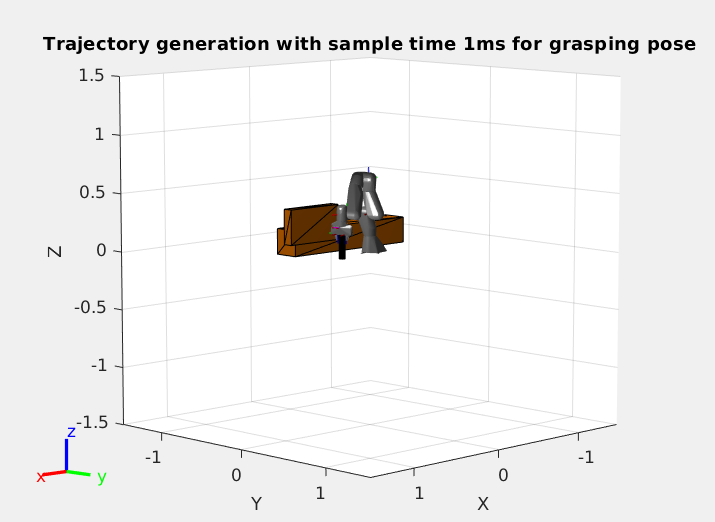

path_size = size(planned_path);

tpts = 0:path_size(1);
sampleRate = 1000;
tvec = tpts(1):1/sampleRate:tpts(end);
numSamples = length(tvec);

rng default
frankaWaypoints = planned_path';
frankaTimepoints = linspace(tvec(1),tvec(end),path_size(1));
% [q,qd] = trapveltraj(frankaWaypoints,numSamples);

% Minimum jerk trajectory
[q,qd,~,~,~,~,tvec] = minjerkpolytraj(frankaWaypoints,frankaTimepoints,numSamples);
% figure
set(gcf,'Visible','on');
for i = 1:10:numSamples % We decimate for faster animation
    show(franka,q(:,i)',FastUpdate=true,PreservePlot=false);
    title("Trajectory generation with sample time 1ms for grasping pose")
    drawnow;
end

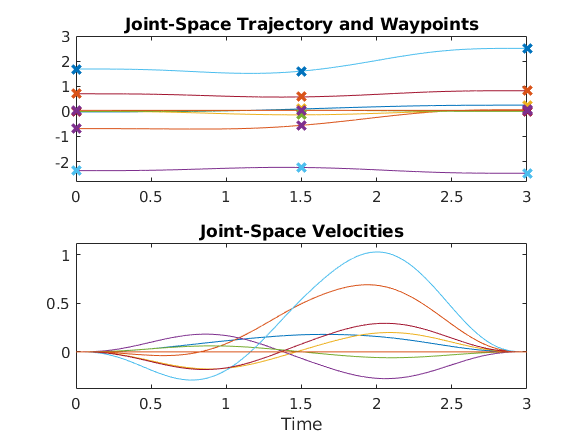

helperPlotJointSpaceTraj('Joint-Space Trajectory and Waypoints', ...
    tvec,q,qd,frankaWaypoints,frankaTimepoints);

## Evaluate the generated trajectory on the real robot!

Make sure the etherent connection is properly established, the breaks and the user-button are released and the FCI mode is activated in Desk. Warning: The robot will move! 

### Let's follow the trajectory we generated!

fr.joint_trajectory_motion(q(1:7,:));

### Now let's grasp the object

object_grasped = fr.Gripper.grasp(.03,.01,.01,0,0);

## Update the world representation

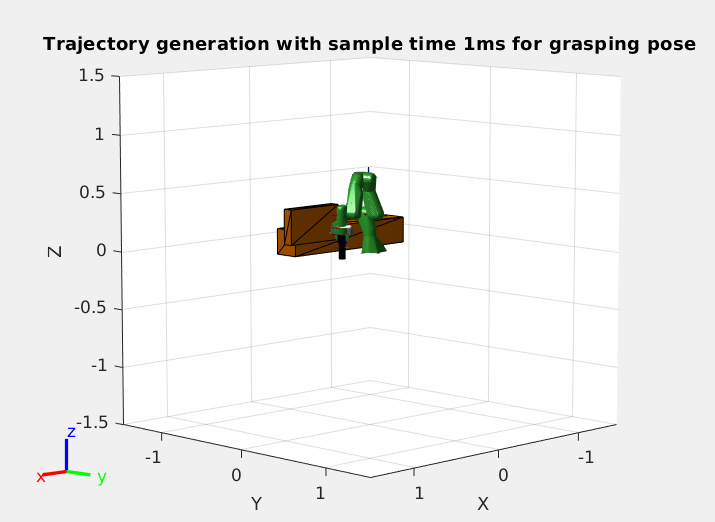

% Create can as a rigid body
cylinder1 = env{3};
canBody = rigidBody("myCan");
canJoint = rigidBodyJoint("canJoint");

% Get current pose of the robot hand.
startConfig = planned_path(end, :);
endEffectorPose = getTransform(franka,startConfig,"panda_hand");

% Place can into the end effector gripper.
setFixedTransform(canJoint,endEffectorPose\cylinder1.Pose); 

% Add collision geometry to rigid body.
addCollision(canBody,cylinder1,inv(cylinder1.Pose));
canBody.Joint = canJoint;

% Add rigid body to robot model.
addBody(franka,canBody,"panda_hand");

% Remove object from environment.
env(3) = [];

figure(f);
show(franka,startConfig,"Visuals","on","Collisions","on");

hold on
for i = 1:length(env)
    show(env{i});
end

## Path Planning for goal configuration with collision avoidance

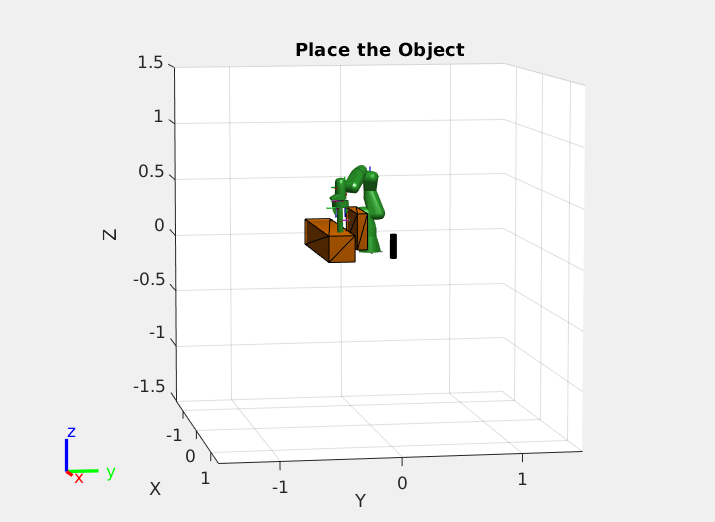

goalConfig = [-0.329655821089159 -0.00274793084976792 -0.306746510403877 -1.90460095409297 0.00565165968147325 1.88028941061331 0.033825705859234 0.04 0.04];

planner = manipulatorRRT(franka, env);

planner.MaxConnectionDistance = 1;
planner.ValidationDistance = 0.2;
planner.EnableConnectHeuristic = false;
planned_path =  plan(planner,startConfig,goalConfig);

interpStates = interpolate(planner,planned_path);

figure(f);
show(franka,config,"Visuals","off","Collisions","on");

for i = 1:size(interpStates,1)
    show(franka,interpStates(i,:),...
        "PreservePlot", false,...
        "Visuals","off",...
        "Collisions","on");
    title("Place the Object")
    drawnow;
    if i == (size(interpStates,1))
        view([80,7])
    end
end

### Optimize generated path with the shorten() function

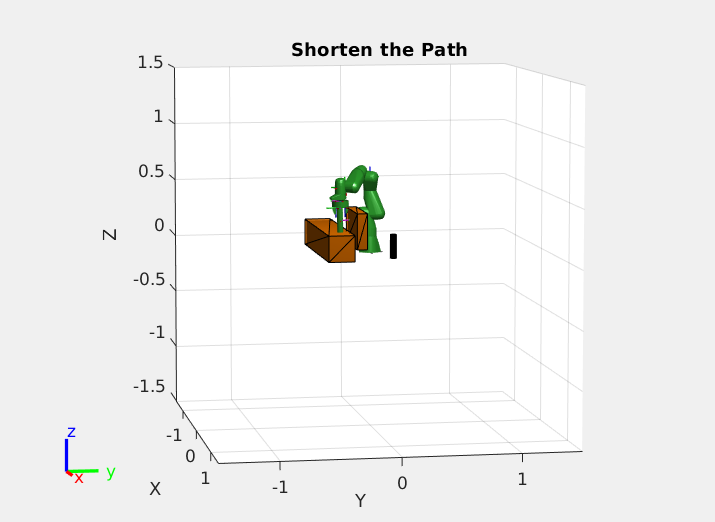

shortenedPath = shorten(planner,planned_path,20);

interpStates = interpolate(planner,shortenedPath);

figure(f);
for i = 1:size(interpStates,1)
    show(franka, ...
        interpStates(i, :),  ...
        "PreservePlot", false, ...
        "Visuals", "off", ...
        "Collisions", "on");
    drawnow;
    title("Shorten the Path")
    if i > (size(interpStates,1)-2)
        view([80,7])
    end
end

## Generate Joint Trajectory

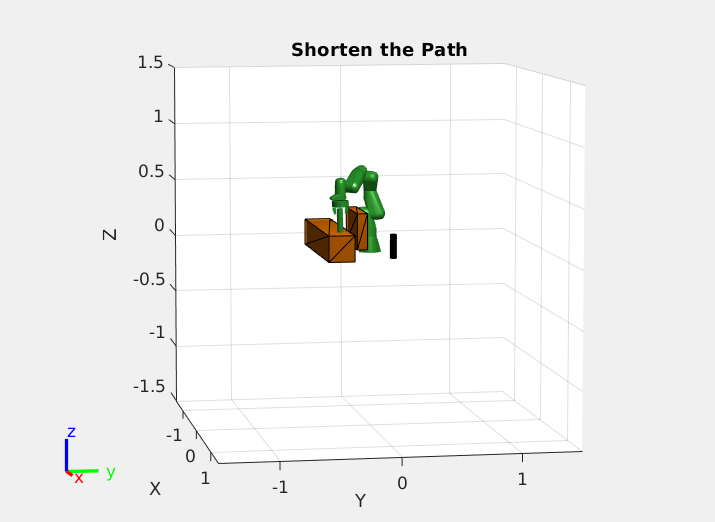

path_size = size(shortenedPath);

tpts = 0:path_size(1);
sampleRate = 1000;
tvec = tpts(1):1/sampleRate:tpts(end);
numSamples = length(tvec);

rng default
frankaWaypoints = shortenedPath';
frankaTimepoints = linspace(tvec(1),tvec(end),path_size(1));
% [q,qd] = trapveltraj(frankaWaypoints,numSamples);

% Minimum jerk trajectory
[q,qd,~,~,~,~,tvec] = minjerkpolytraj(frankaWaypoints,frankaTimepoints,numSamples);

figure(f);
rc = rateControl(sampleRate);
for i = 1:10:numSamples % We decimate for faster animation
    show(franka,q(:,i)',FastUpdate=true,PreservePlot=false,Collisions="on");
    waitfor(rc);
end

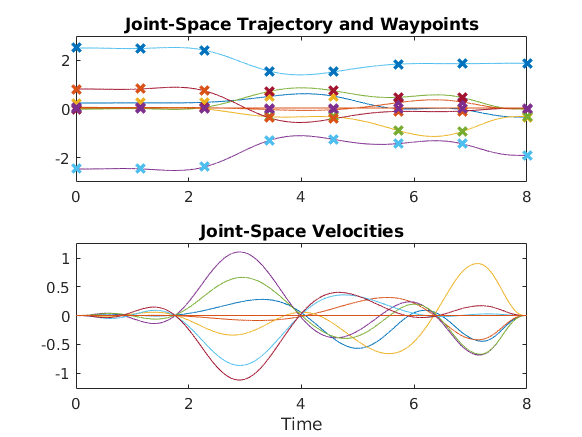

helperPlotJointSpaceTraj('Joint-Space Trajectory and Waypoints', ...
    tvec,q,qd,frankaWaypoints,frankaTimepoints);

## Evaluate on the Franka Robot

Attempt flushing any current potential error states with the automatic_error_recovery(); command

fr.joint_trajectory_motion(q(1:7,:));

### Release the object

fr.Gripper.stop();
fr.Gripper.move(fr.Gripper.state().max_width,.1)

ans = logical
   1
